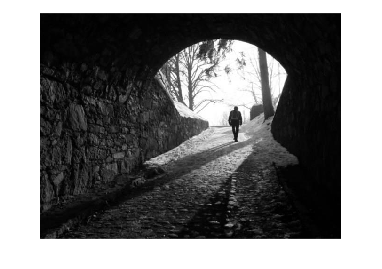

% Load image
I = truecolorload('./images/3before.png');
I = I(:,:,1);
imshow(I);

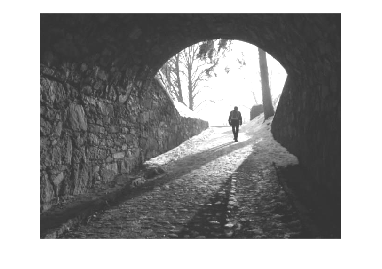


[m, n] = size(I, 1, 2);

% Convert to DCT
J = dct2(I);

% imshow(log(abs(J)),[]),
% colormap(gca,jet(64)), colorbar

% 'Contrast'
CR = 1;
J = J .* CR;

% 'Brightness'
BR = 2;
J(1, 1) = J(1, 1) * BR ./ CR;


% Revert to Spatial
O = idct2(J);
imshow(O, [0 256]);